Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Cantor set (Section 9.6)

Volker Ziemann, 211116, CC-BY-SA-4.0

This script produces the cantor set, shown in Figure 9.5. It is defined by repeatedly removing the center third of every line segment. In the figure we start with a line from 0 to 1, then remove the third in the middle to obtain the second generation shown immediately below the solid line at the top. Then we just repeat the procedure. 

In the code we define the number of iterations and draw the solid line at the top and specify the axes. The array `start` contains the start point of each line segment and in the beginning this is only the start of the solid line at zero. The varaible `seg` holds the number of segements in from generation to generation.

generations=6; 
plot([0,1],[0,0],'Linewidth',10,'Color','k')
axis([-0.02,1.02, -1-generations 1])
start=[0];
seg=1;

Now we loop over the desired number of generations, update the number of segements in the present generations to 3 times the prievious number and calculate the length of each segment. 

for k=1:generations
  segprev=seg;    % previous number of segments
  seg=seg*3;      % present number of segments
  lll=1/seg;      % length of each segment

Then we update `start` with the additional points and plot the line segments.

  start=[start,start+2*segprev]; % starting point of each line
  for m=1:length(start)  % plot the line
    line([start(m)*lll,(start(m)+1)*lll],[-k,-k],'Linewidth',10,'Color','k')
  end
end

In the end we annotate the axes and remove unnecessary tick marks.

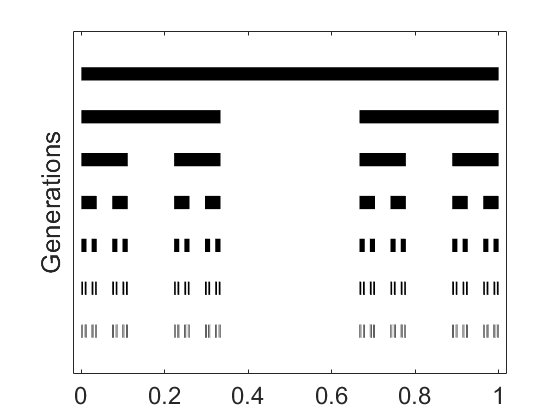

ylabel('Generations')
set(gca,'FontSize',18)
set(gca,'YTick', [])